# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

thisR.set('light','all','delete');

The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

thisLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',thisLight, 'add');
thisR.set('light',thisLight.name,'specscale',0.5);
thisR.set('light',thisLight.name,'spd',[0.5 0.4 0.2]);

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces

### AJ: Docker for Remote Rendering

% thisdocker = isetdocker;
% thisdocker.gpuRendering = 1;
% thisdocker.localRender = 0;
% thisdocker.remoteResources = 1;
% thisdocker.renderContext = 'remote-orange';
% thisdocker.remoteMachine = 'orange.stanford.edu';
% thisdocker.remoteImage = 'ditigalprodev/pbrt-v4-ampere-orange'
% thisdocker.whichGPU = 0;
% thisdocker.verbosity = 1;
% thisdocker.defaultContext = 'default';
% thisdocker.localImage = '1';
% thisdocker.remoteUser = 'amj18';
% thisdocker.remoteRoot = '/home/amj18';
% thisdocker.localRoot = '';

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera, so that we are effectively rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

thisD = isetdocker;
scene = piRender(thisR, 'docker', thisD);

[INFO]: STARTED Docker successfully
[INFO]: Uploading data:
[INFO]: Sent 1408 bytes  received 380 bytes  63629 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-ayushjam12076 sh -c " pbrt  --gpu  --outfile /home/amj18/ISETRemoteRender/sphere/renderings/sphere.exr /home/amj18/ISETRemoteRender/sphere/sphere.pbrt "
[INFO]: Rendered remotely in: 21.74 sec
[INFO]: Downloading data:
[INFO]: Sent 584 bytes  received 384 bytes  9680000 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/sphere.exr


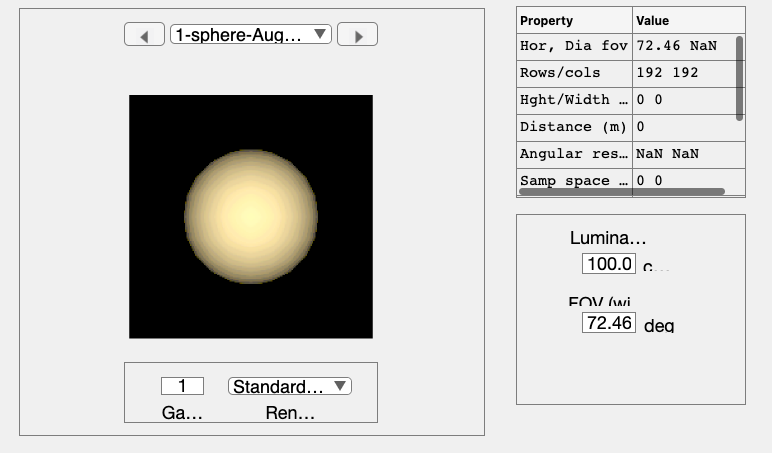

sceneWindow(scene);

% dockerWrapper.getPrefs;
[scene, result] = piRender(thisR);
sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

% Remove the light we added
thisR.set('light',thisLight.name, 'delete');

% Create a new version with a different color temperature
thisLight = piLightCreate('distant','type','distant',  'spd', 9000,  'cameracoordinate', true);
thisR.set('light',thisLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

piWRS(thisR);

## Read an  FBX file and write it as PBRT

% FBX is converted into PBRT
fname = fullfile(piRootPath,'data','scenes','teapot-set','TeaTime-converted.pbrt');
 
thisR  = piRead(fname);

Convert scene unit from centimeter to meter

thisR.set('film resolution',[600 600]/2);
thisR.set('rays per pixel',32);

Set the render type.

One type is radiance, and here are the others

**rTypes = {'radiance','depth','both','all','coordinates','material','instance', 'illuminant','illuminantonly'};**

thisR.set('film render type',{'radiance','depth'});

%% move object
thisR.set('asset','Cylinder.001_B','world translation',[0.2 0 0]);

thisR.show('objects');

## Add a light

thisR.set('lights','all','delete');
lightName = 'new light';
newLight = piLightCreate(lightName,...
                        'type','infinite',...
                        'spd',[0.4 0.3 0.3],...
                        'specscale',1);
thisR.set('light', newLight, 'add');

% Render and return the scene
scene = piWRS(thisR);

Show the geometry

piAssetGeometry(thisR);view(-80,-65);